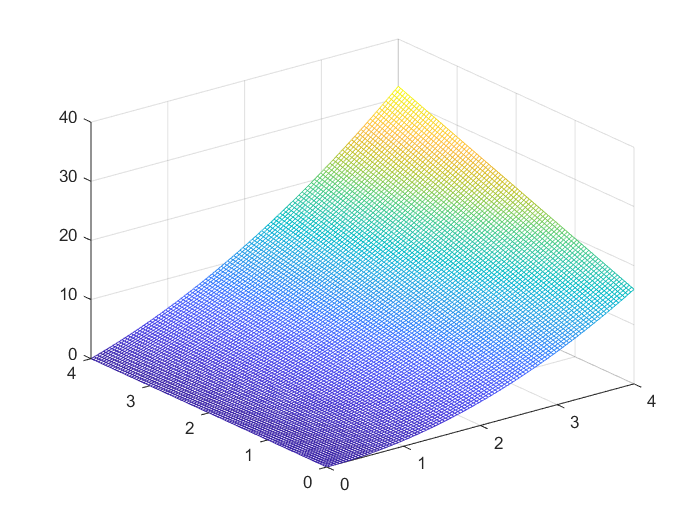

x1= linspace(0,4);
x2 = linspace(0,4);
[X1,X2] = meshgrid(x1,x2);
f1=X1.^2 + X1.*X2;
f2= X2 + 3*X1.*X2.^2;
mesh(X1,X2,f1);

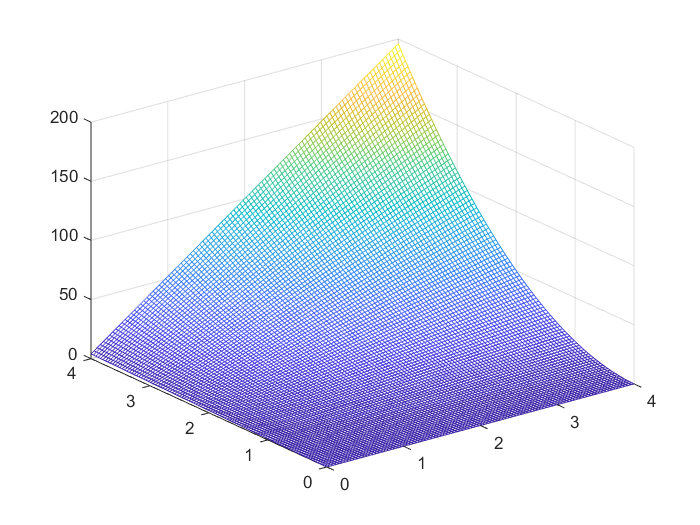

mesh(X1,X2,f2);

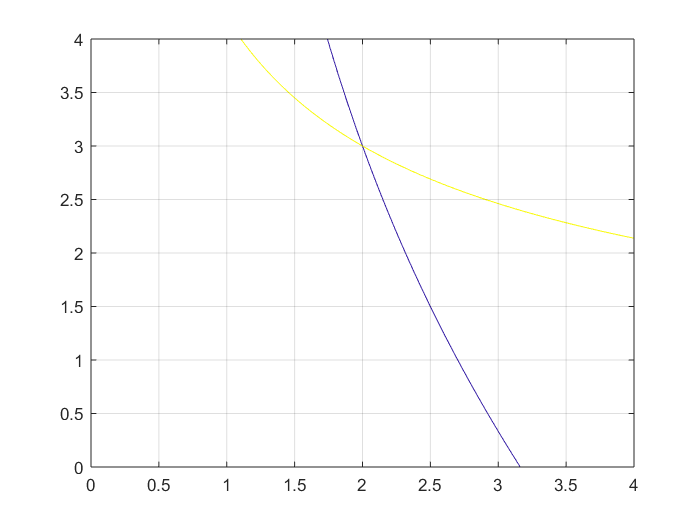

contour(X1,X2,f1,[10 10]);
hold on;
contour(X1,X2,f2,[57 57]);
grid on
hold off;

f= @(x) [x(1)^2 + x(1)*x(2)-10;
        x(2)+3*x(1)*x(2)^2-57]; %vector 
J= @(x) [2*x(1)+x(2), x(1);
         3*x(2)^2, 1+6*x(1)*x(2)];  %Matriz
x0= [1;1];
[x,i] = NewthonRaphsonVV(f,J,x0)

x =    2.000000000000000
   3.000000000000000


i =      8


syms x1 x2 
xs= [x1;x2];
f1=xs(1)^2+xs(1)*xs(2)-10;
f2 = xs(2) + 3*xs(1)*xs(2)^2-57;
fs=[f1;f2];

$$fs = \left(\begin{array}{c} {x_{1}}^{2}+x_{2}\,x_{1}-10\\ 3\,x_{1}\,{x_{2}}^{2}+x_{2}-57 \end{array}\right)$$

f = matlabFunction(fs);

f = function_handle with value:
    @(x1,x2)[x1.*x2+x1.^2-1.0e+1;x2+x1.*x2.^2.*3.0-5.7e+1]


Js=jacobian(fs,xs);

$$Js = \left(\begin{array}{cc} 2\,x_{1}+x_{2} & x_{1}\\ 3\,{x_{2}}^{2} & 6\,x_{1}\,x_{2}+1 \end{array}\right)$$

J = matlabFunction(Js);

J = function_handle with value:
    @(x1,x2)reshape([x1.*2.0+x2,x2.^2.*3.0,x1,x1.*x2.*6.0+1.0],[2,2])


#### Problema de 3 esferas

(x1-a)^2 + (x2-b)^2 + (x3-c)^2 = r^2 

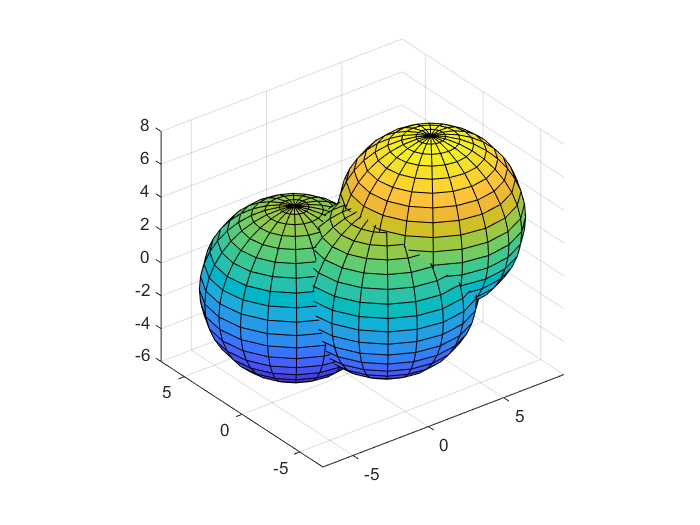

[x,y,z]= sphere;

figure 
surf(x,y,z)
axis equal;
hold on
%radio = 5 c=[4,-2,3]
surf(x*5+4, y*5-2, z*5+3)
axis equal;

%radio =5 c=[1,-2,0]
surf(x*5+1, y*5-2, z*5)
axis equal;

%radio =5 c=[-2,2,-1]
surf(x*5-2, y*5+2, z*5-1)
axis equal;


fr = @(x) [(x(1)-4)^2+(x(2)+2)^2+(x(3)-3)^2-5^2;
        (x(1)-1)^2+(x(2)+2)^2+(x(3))^2-5^2;
        (x(1)+2)^2+(x(2)-2)^2+(x(3)+1)^2-5^2];
    
Jr = @(x) [2*(x(1)-4),2*(x(2)+2),2*(x(3)-3);
          2*(x(1)-1),2*(x(2)+2),2*x(3);
          2*(x(1)+2),2*(x(2)-2),2*(x(3)+1)];

x0 = [-1;-1;-1];
[x,i] = NewthonRaphsonVV(fr,Jr,x0)

x =     1.0000
    2.0000
    3.0000


i = 12


x0 = [1;1;1];
[x,i] = NewthonRaphsonVV(fr,Jr,x0)

x =     1.8889
    2.4444
    2.1111


i = 11

3x1 - cos(x1x2) = 3/2

4x1^2 - 625x2^2 + 2x2 =1

e^(-x1x2) + 20x3 = (10pi -3)/3

e = exp

% newtown raphson, condición inicial [0 0 0]